# Bell+ halo time-evolution

Demo magnetic gradiometry by time-evolution of $\vert\Psi^+\rangle$ halo

DKS

2018-10-25

## load data

% TODO: traverse dataset
path_dir='C:\Users\HE BEC\Documents\lab\bell_momentumspin\bell_epr_2018\proc\exp5_bell_yrot';
fname_data='idealgrot_4_20180814_1';
path_data=fullfile(path_dir,fname_data);

load(path_data);        % load data
close all;  % tidy figures

## get k-vecs in opposite regions

% configs
% capture section
% TODO: traverse regions
V_az=3/5*pi;
V_el=0;
alpha=pi/8;

% get data
% TODO: traverse TEVO
K=k_par{1};    % load k-data into K
tau=0.8e-3;    % time evolution
% TODO get from fname/metadata 0.8 ms
%    attach metadata manually - dir name

% capture vecs in section
[~,b_A]=cellfun(@(x) inCone(x,V_az,V_el,alpha),K,'UniformOutput',false);        % in A   
[~,b_B]=cellfun(@(x) inCone(x,V_az+pi,-V_el,alpha),K,'UniformOutput',false);    % in B
b_AB=cellfun(@(b1,b2) b1|b2,b_A,b_B,'UniformOutput',false);        % in both

k_in=cellfun(@(x,b) x(b,:),K,b_AB,'UniformOutput',false);

figure;
plot_zxy(k_in);

## g2 analysis

Elapsed time is 7.184640 seconds.


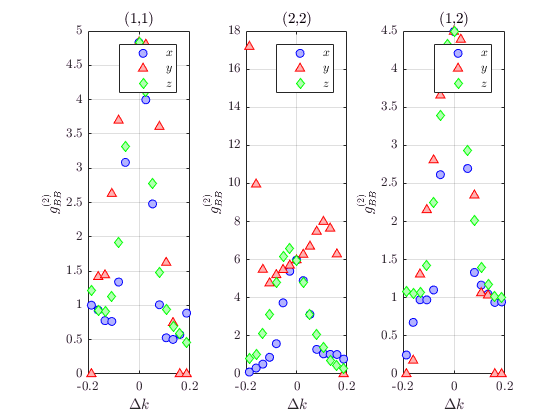

% configs
n_bins=15;      % original: 29
dk_ed_vec=linspace(-0.2,0.2,n_bins+1);      % original: [-0.2,0.2]
dk_cent_vec=dk_ed_vec(1:end-1)+0.5*diff(dk_ed_vec);
[~,idx_dk0]=min(abs(dk_cent_vec));    % idx bin nearest zero
dk_ed={dk_ed_vec,dk_ed_vec,dk_ed_vec};
dk_grid_size=cellfun(@(k) length(k)-1,dk_ed);

% g2
[g2,dk,g2mdl]=summary_disthalo_g2(k_in,dk_ed,0,1,0,1);


% corr strength
g0=cellfun(@(g) g(idx_dk0,idx_dk0,idx_dk0),g2);    % at BB

% correlator
[B,B0]=g2toE(mean(g0(1:2)),g0(3));

## bootstrapping

% configs
bs_frac=0.3;        % sampling frac size
bs_nrep=10;           % # repeats

% set up
n_data_size=size(k_in,1);
bs_nsamp=round(bs_frac*n_data_size);    % # data to sample for bs

bs_Isamp=cellfun(@(c) randi(n_data_size,[bs_nsamp,1]), cell(bs_nrep,1),...
    'UniformOutput',false);

% bootstrapping
% g2
g2_bs=cellfun(@(I) summary_disthalo_g2(k_in(I,:),dk_ed,0,0,0,0),bs_Isamp,...
    'UniformOutput',false);
g2_bs=cat(1,g2_bs{:});    % g2 dist from bs
g0_bs=cellfun(@(g) g(idx_dk0,idx_dk0,idx_dk0),g2_bs);    % corr strength

% B
[B_bs,B0_bs]=g2toE(mean(g0_bs(:,1:2),2),g0_bs(:,3));

% statistics
g0_bs_mu=mean(g0_bs,1);
g0_bs_se=sqrt(bs_frac)*std(g0_bs,0,1);

B_bs_mu=mean(B_bs,1);
B0_bs_mu=mean(B0_bs,1);
B_bs_se=sqrt(bs_frac)*std(B_bs,0,1);
B0_bs_se=sqrt(bs_frac)*std(B0_bs,0,1);

## Data vis: configs

[c,cl,cd]=palette(3);
% c_gray=0.6*ones(1,3);
% line_sty={'-','--',':'};
% mark_typ={'o','s','^'};
% str_ss={'$\vert\!\uparrow\rangle$','$\vert\!\downarrow\rangle$'};
% str_ss={'$m_J = 1$','$m_J = 0$'};
str_ss={'$\uparrow\uparrow$','$\downarrow\downarrow$','$\uparrow\downarrow$'};
mark_siz=7;
line_wid=1.5;
fontsize=12;
ax_lwidth=1.2;

## data vis: g2 correlation strength

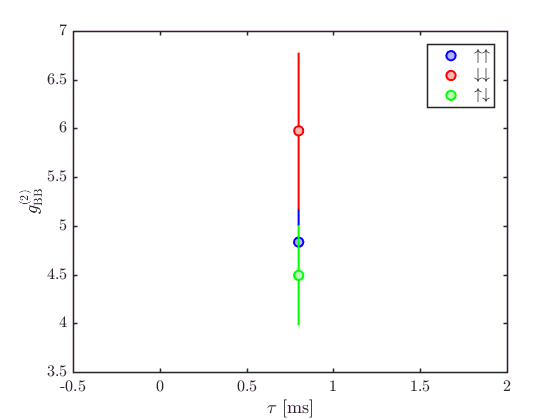

% figure
figure('Name','demo_g');
hold on;

pleg=NaN(3,1);
for ii=1:3
    tp=myploterr(1e3*tau,g0(:,ii),[],g0_bs_se(:,ii),'o',c(ii,:));
    set(tp(1),'MarkerSize',mark_siz,'LineWidth',line_wid,'Displayname',str_ss{ii});
    pleg(ii)=tp(1);
    set(tp(2),'LineWidth',line_wid);
end

% annotate
box on;
ax=gca;
xlabel('$\tau~[\textrm{ms}]$');
ylabel('$g^{(2)}_{\mathrm{BB}}$');
ax.FontSize=fontsize;
ax.LineWidth=1.2;

lgd=legend(pleg);
lgd.FontSize=fontsize;

## data vis: Correlator/Parity

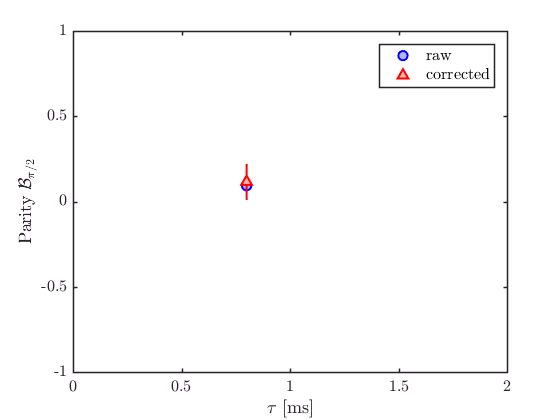

% figure
figure('Name','demo_correlator');
hold on;
p=myploterr(1e3*tau,B,[],B_bs_se,'o',[0,0,1]);
set(p(1),'MarkerSize',mark_siz,'LineWidth',line_wid,'Displayname','raw');
set(p(2),'LineWidth',line_wid);
p_bs=myploterr(1e3*tau,B0,[],B0_bs_se,'^',[1,0,0]);
set(p_bs(1),'MarkerSize',mark_siz,'LineWidth',line_wid,'Displayname','corrected');
set(p_bs(2),'LineWidth',line_wid);

% annotate
box on;
ax=gca;
xlabel('$\tau~[\textrm{ms}]$');
ylabel('Parity $\mathcal{B}_{\pi/2}$');
ax.FontSize=fontsize;
ax.LineWidth=1.2;
txlim=ax.XLim;
xlim([0,txlim(2)]);
ylim([-1,1]);

lgd=legend([p(1),p_bs(1)]);
lgd.FontSize=fontsize;